clear

% Load the epocheddata.
%load smilefrown1filt0p5notch56t64epochs.mat
%load smilefrown2filt0p5notch56t64epochs.mat
%load smilefrown2filt0p5notch56t64p120epoch.mat
load run15filt0p5doublenotch56t64a120epochs.mat

EEG.timessec = EEG.times./1000; %version of times in seconds, useful for signal processing
origEEGdata = EEG.data;


load colormapjetwhite.mat; %loads cmapwj to do a colormap with white instead of green for jet


% Create a new categorical variable for easier manipulation.
% Note, this will be inaccurate if you select a subset of the data without
% subsetting this.
for epoch = 1:EEG.trials
    for i = 1:length(EEG.epoch(epoch).eventlatency)
        if EEG.epoch(epoch).eventlatency{i} == 0
            EEG.epochlabelscat{epoch} = EEG.epoch(epoch).eventtype{i};
        end
    end
end
EEG.epochlabelscat = categorical(EEG.epochlabelscat);
%make an array of all possible labels of events in your data
availableeventlabels = unique(EEG.epochlabelscat)

availableeventlabels = 1×15 categorical array
     BadDrop      C pressed      Completed1      Completed2      Completed3      Completed4      DOWN pressed      F pressed      GameOver      LEFT pressed      RIGHT pressed      S pressed      SPACE pressed      SPACE released      UP pressed 


%We'll use this to index which epochs we want


Do any additional filtering that you want (currently another high pass at 20 hz) and also find power first or skip this

for channel =1:size(EEG.data,1)
    % First, save the power in the frequency comain
    [EEG.freqcalcs.P(channel,:,:),EEG.freqcalcs.F] = pspectrum(squeeze(EEG.data(channel,:,:)),EEG.timessec);
    
    EEG.data(channel,:, :) = highpass(squeeze(EEG.data(channel,:, :)),20,EEG.srate);
end


Determine what time window to look in

timewindowforfeatures = [200 800]; %start and stop in ms. If timepoints don't line up, this will select a slightly later time
timewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));


Recalculate freq power in time window

for channel =1:size(EEG.data,1)
    % First, save the power in the frequency comain
    [EEG.freqcalcswindow.P(channel,:,:),EEG.freqcalcswindow.F] = pspectrum(squeeze(EEG.data(channel,timewindowepochidx,:)),EEG.timessec(timewindowepochidx));    
end
EEG.freqcalcswindow.meanP = mean(EEG.freqcalcswindow.P,3);
EEG.freqcalcswindow.stdP = std(EEG.freqcalcswindow.P,0,3);

Now, we're trying to develop an average across trials. This is probably not the right way to do this, but might be a reasonable starting point (need more research on appropriate way to do statistics here. 

First, create indices for the types of trials you want to look at:

condname = "S pressed"

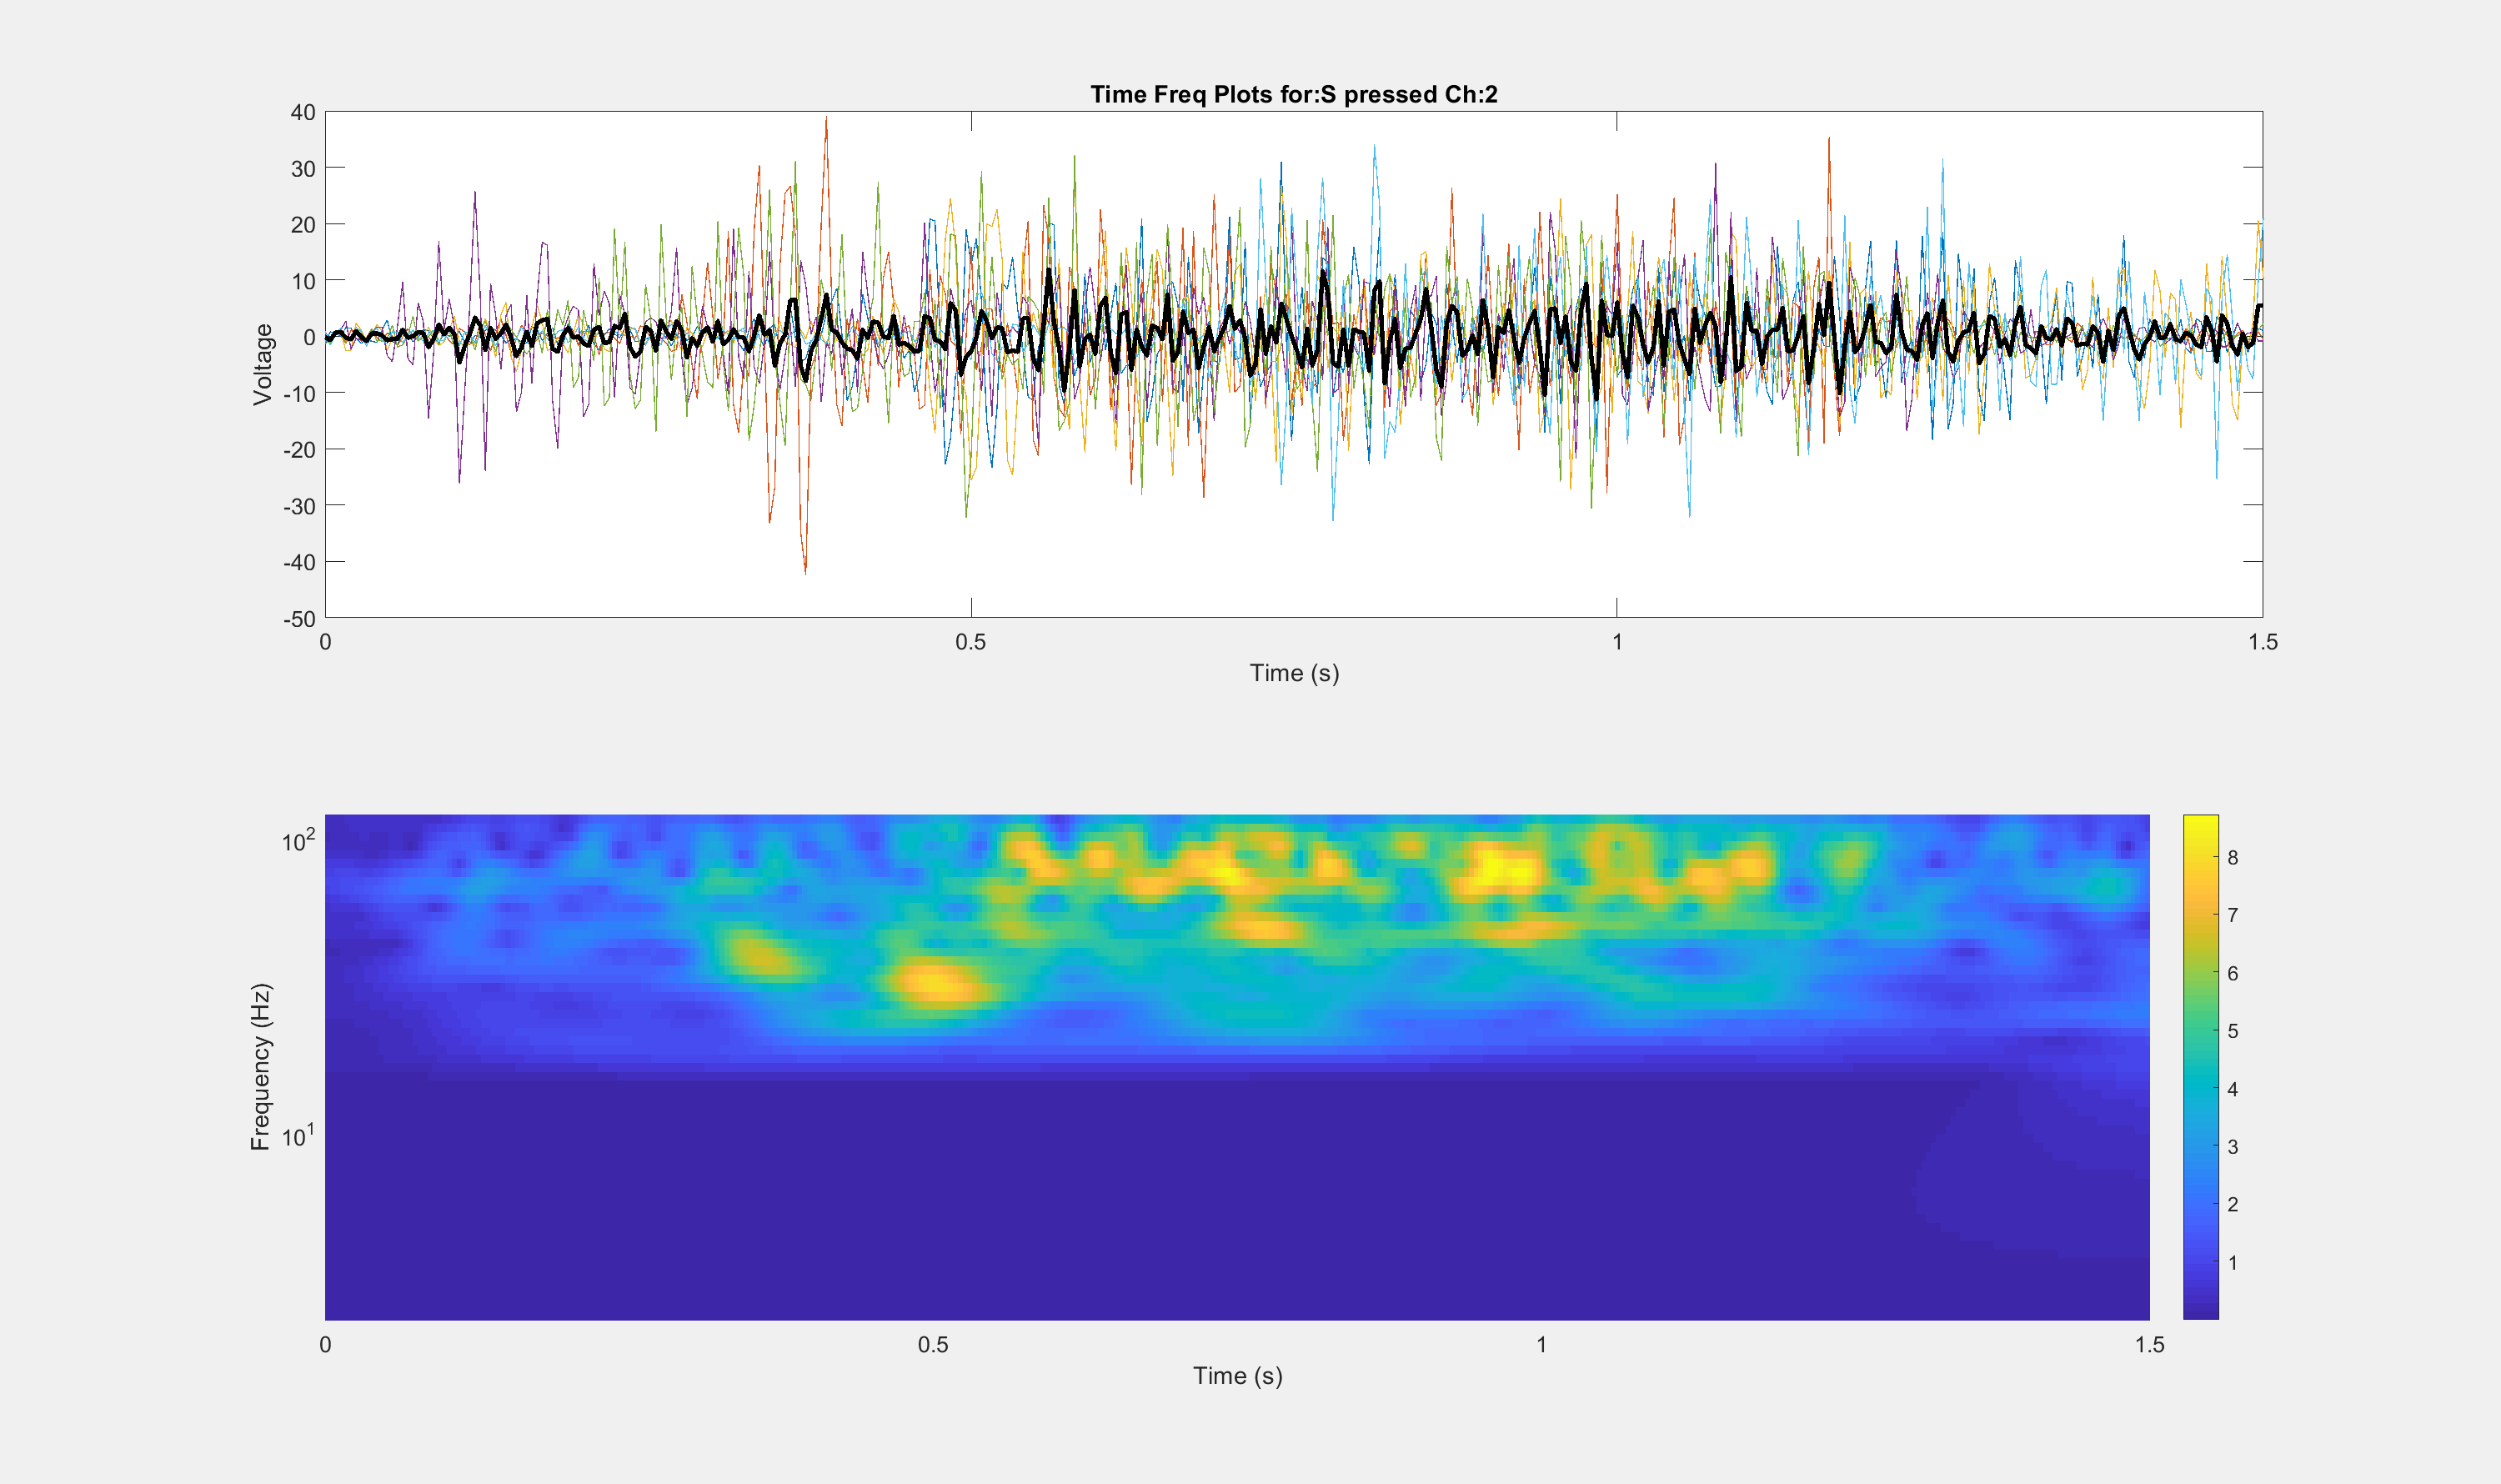

condname = "F pressed"

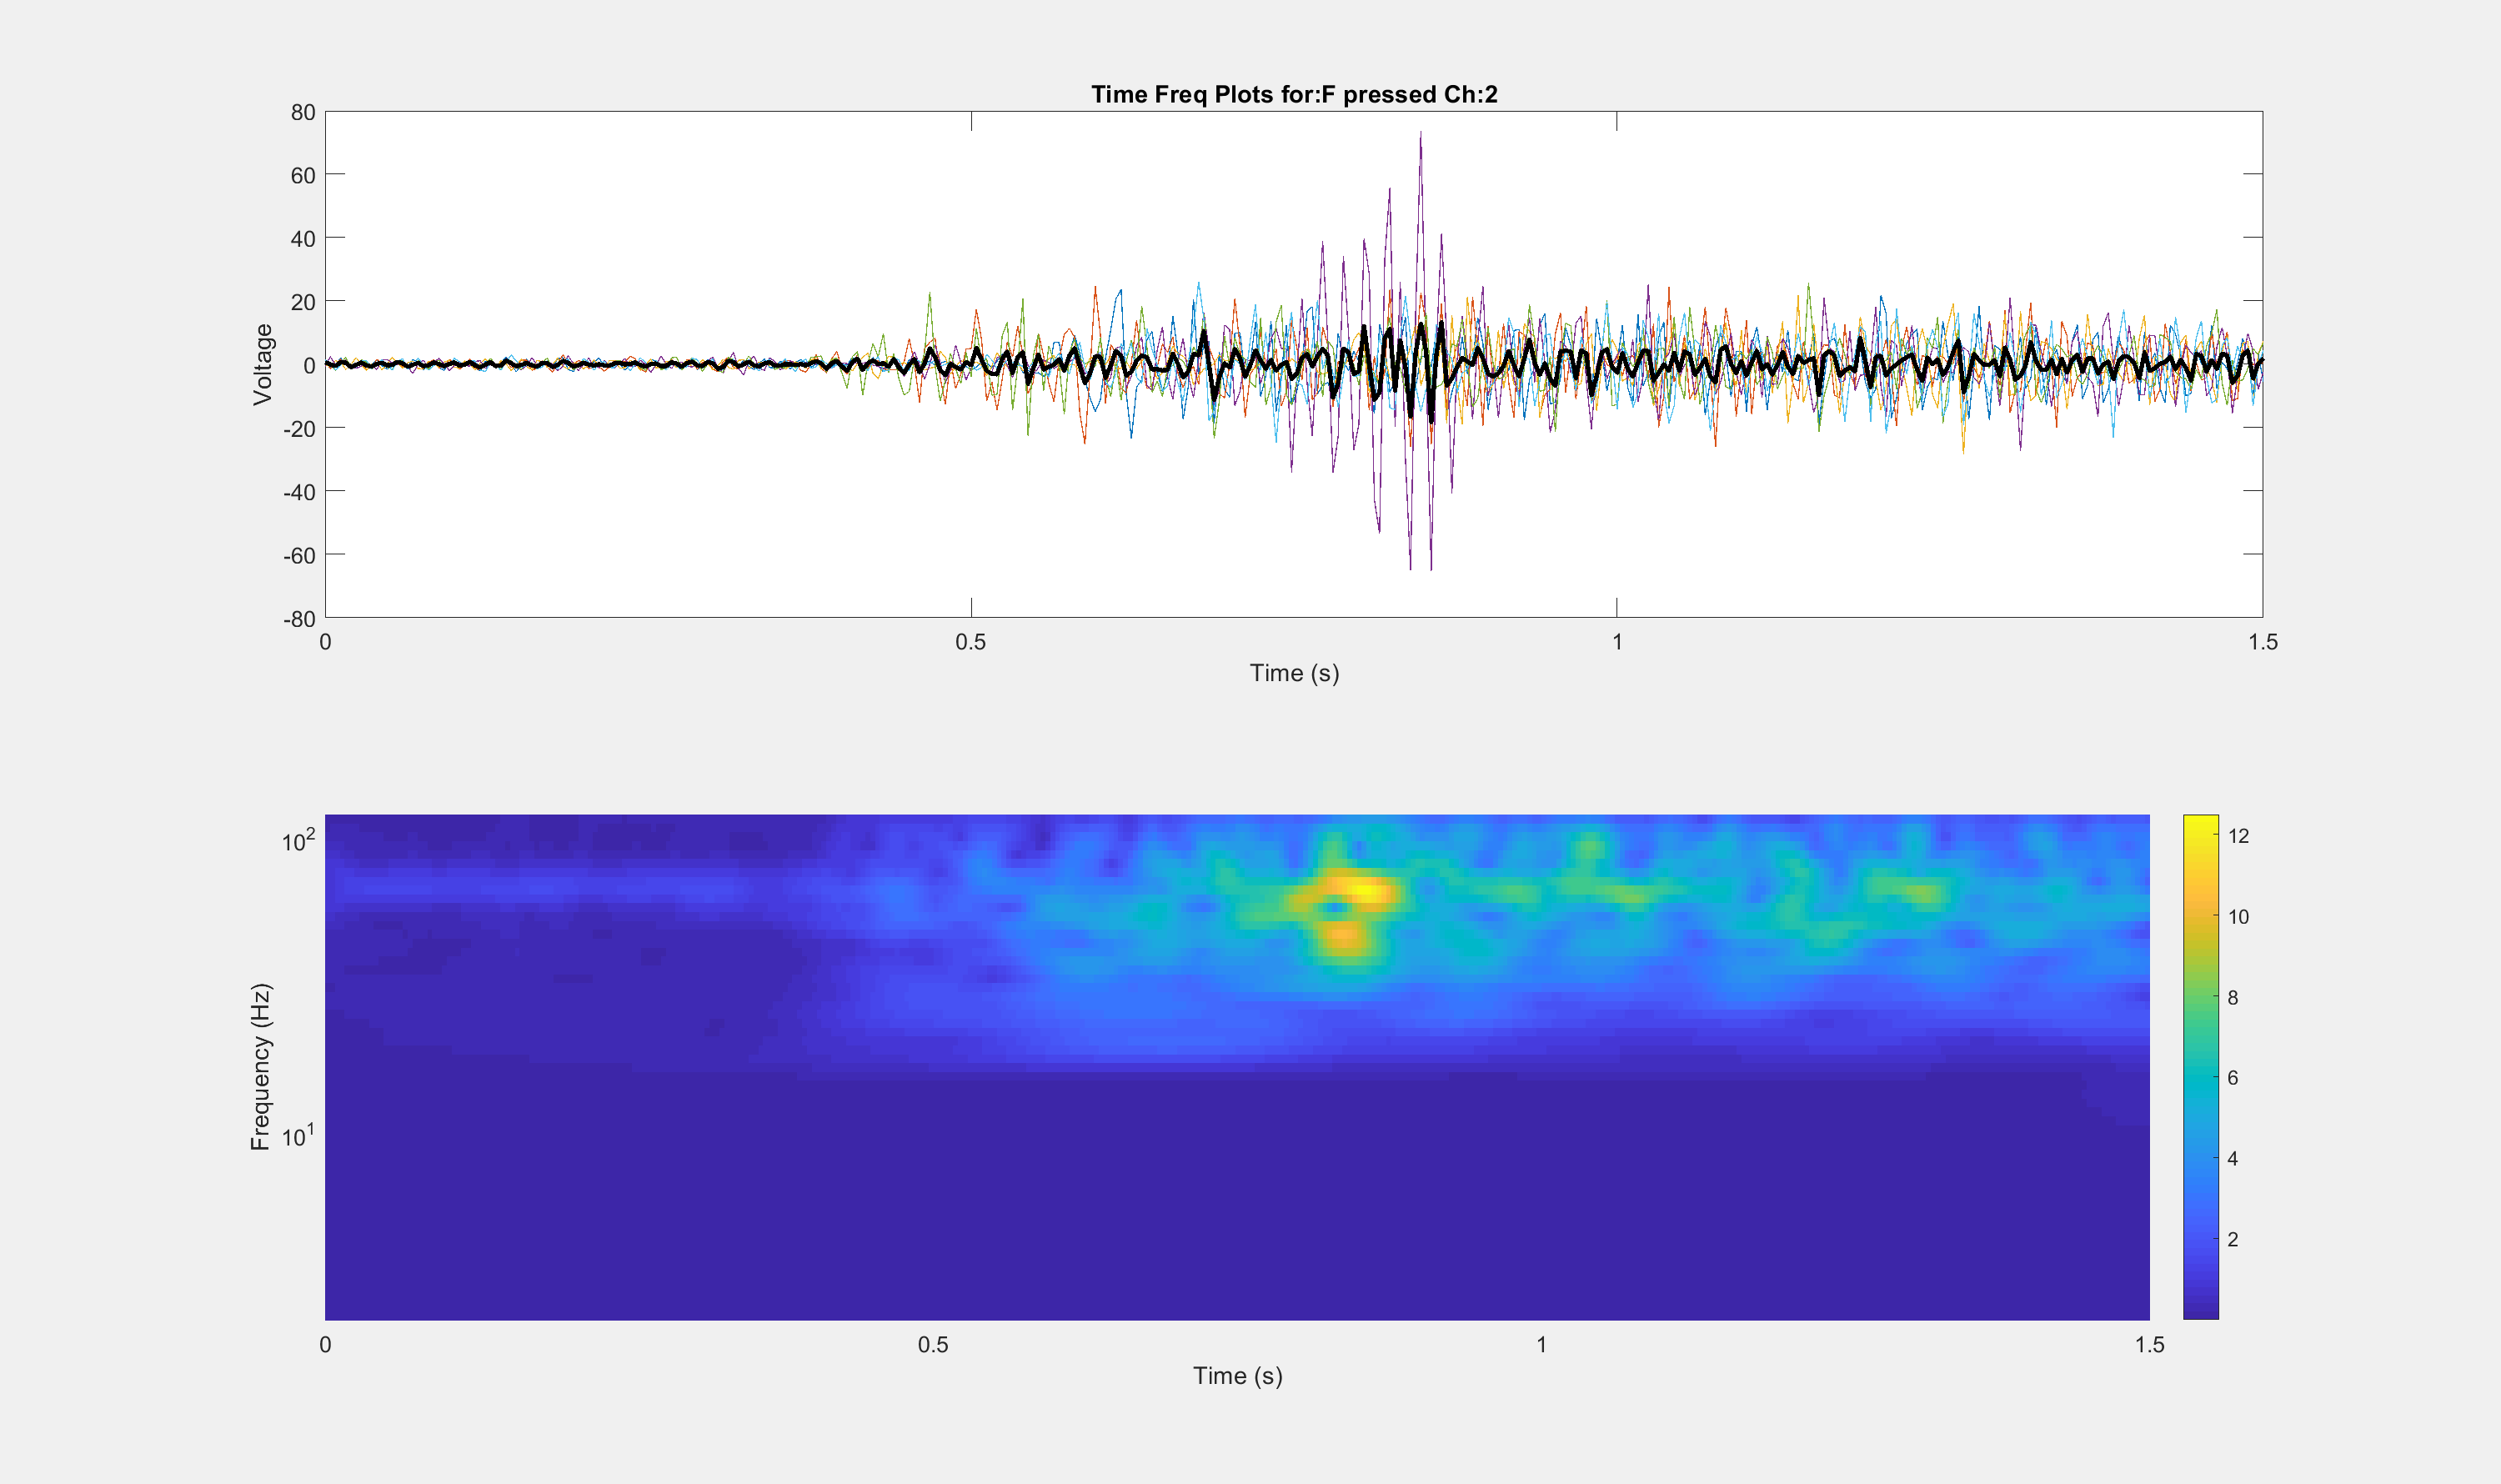

condnames = {"S pressed", "F pressed"};
channel = 2;

for c = 1:length(condnames)
    
    condname = condnames{c}
    idxtrials = find(EEG.epochlabelscat==condname);
     
    % Mean of timecourse
    meantimecourse = mean(squeeze(EEG.data(channel,timewindowepochidx, idxtrials)),2); 
    
    cfs=[];
    for i  = 1:length(idxtrials)
        [cfs(i,:,:),frq] = cwt(double(EEG.data(channel,timewindowepochidx, idxtrials(i))),EEG.srate,'FrequencyLimits',[2 120]);
    end
    tms = EEG.times(timewindowepochidx)./1000; % time axes in seconds% (0:numel(double(EEG.data(channel,timewindowepochidx, idxtrials(1))))-1)/EEG.srate);
    
    meancfs = squeeze(mean(abs(cfs),1));
    
    figure
    set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
    % Time series
    subplot(2,1,1)
    plot(EEG.timessec(timewindowepochidx), squeeze(EEG.data(channel,timewindowepochidx, idxtrials))); ylabel('Voltage'); xlabel('Time (s)');
    hold on
    plot(EEG.timessec(timewindowepochidx), meantimecourse,'k','LineWidth',2);
    title(strcat('Time Freq Plots for: ', condname,' Ch: ', num2str(channel)));
    %Continuous wavelet transform (average)
    subplot(2,1,2)
    %surface(tms,frq,abs(cfs))
    surface(tms,frq,meancfs) % moved abs to before we take the mean
    colorbar;
    axis tight
    shading flat
    xlabel('Time (s)')
    ylabel('Frequency (Hz)')
    set(gca,'yscale','log')
end

Now we're going to do an even worse version of this where we try to estimate the differences between two conditions.

%condnames = {"S pressed", "F pressed"};
%condnames = {"Completed1","DOWN pressed"};
channel = 2;
for c = 1:length(condnames)
    condname = condnames{c}
    idxtrials = find(EEG.epochlabelscat==condname);

    % Mean of timecourse
    condstruc(c).meantimecourse = mean(squeeze(EEG.data(channel,timewindowepochidx, idxtrials)),2);
    condstruc(c).stdtimecourse = std(squeeze(EEG.data(channel,timewindowepochidx,idxtrials)),0,2);  % Compute 'Standard Error Of The Mean'
    condstruc(c).semtimecourse = condstruc(c).stdtimecourse./sqrt(length(idxtrials)); 
    CI95 = tinv([0.025 0.975], length(idxtrials)-1); % Calculate 95% Probability Intervals Of t-Distribution
    condstruc(c).yCI95timecourse = bsxfun(@times, condstruc(c).semtimecourse, CI95(:)');              % Calculate 95% Confidence Intervals
    
    for i  = 1:length(idxtrials)
        [condstruc(c).cfs(i,:,:),frq] = cwt(double(EEG.data(channel,timewindowepochidx, idxtrials(i))),EEG.srate,'FrequencyLimits',[2 120]);
    end
    tms = EEG.times(timewindowepochidx)./1000; % time axes in seconds% (0:numel(double(EEG.data(channel,timewindowepochidx, idxtrials(1))))-1)/EEG.srate);
    
    condstruc(c).meancfs = squeeze(mean(abs(condstruc(c).cfs),1)); %adding an abs here to get magnitude
    condstruc(c).stdcfs = squeeze(std(abs(condstruc(c).cfs))); % may actually want to do the stdev across all time w/in a freq too
     
    
    % Fine the mean frequency power in each condition
    condstruc(c).freqcalcswindow.meanP = squeeze(mean(EEG.freqcalcswindow.P(channel,:,idxtrials),3))';
    condstruc(c).freqcalcswindow.stdP = squeeze(std(EEG.freqcalcswindow.P(channel,:,idxtrials),0,3))';
end

condname = "S pressed"

condname = "F pressed"

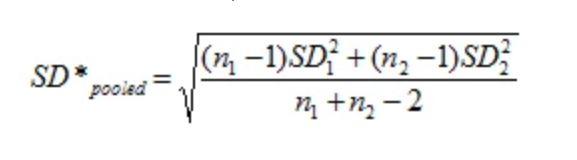

Now calculate a crappy version of a zscore or d score using the pooledweighted stdev

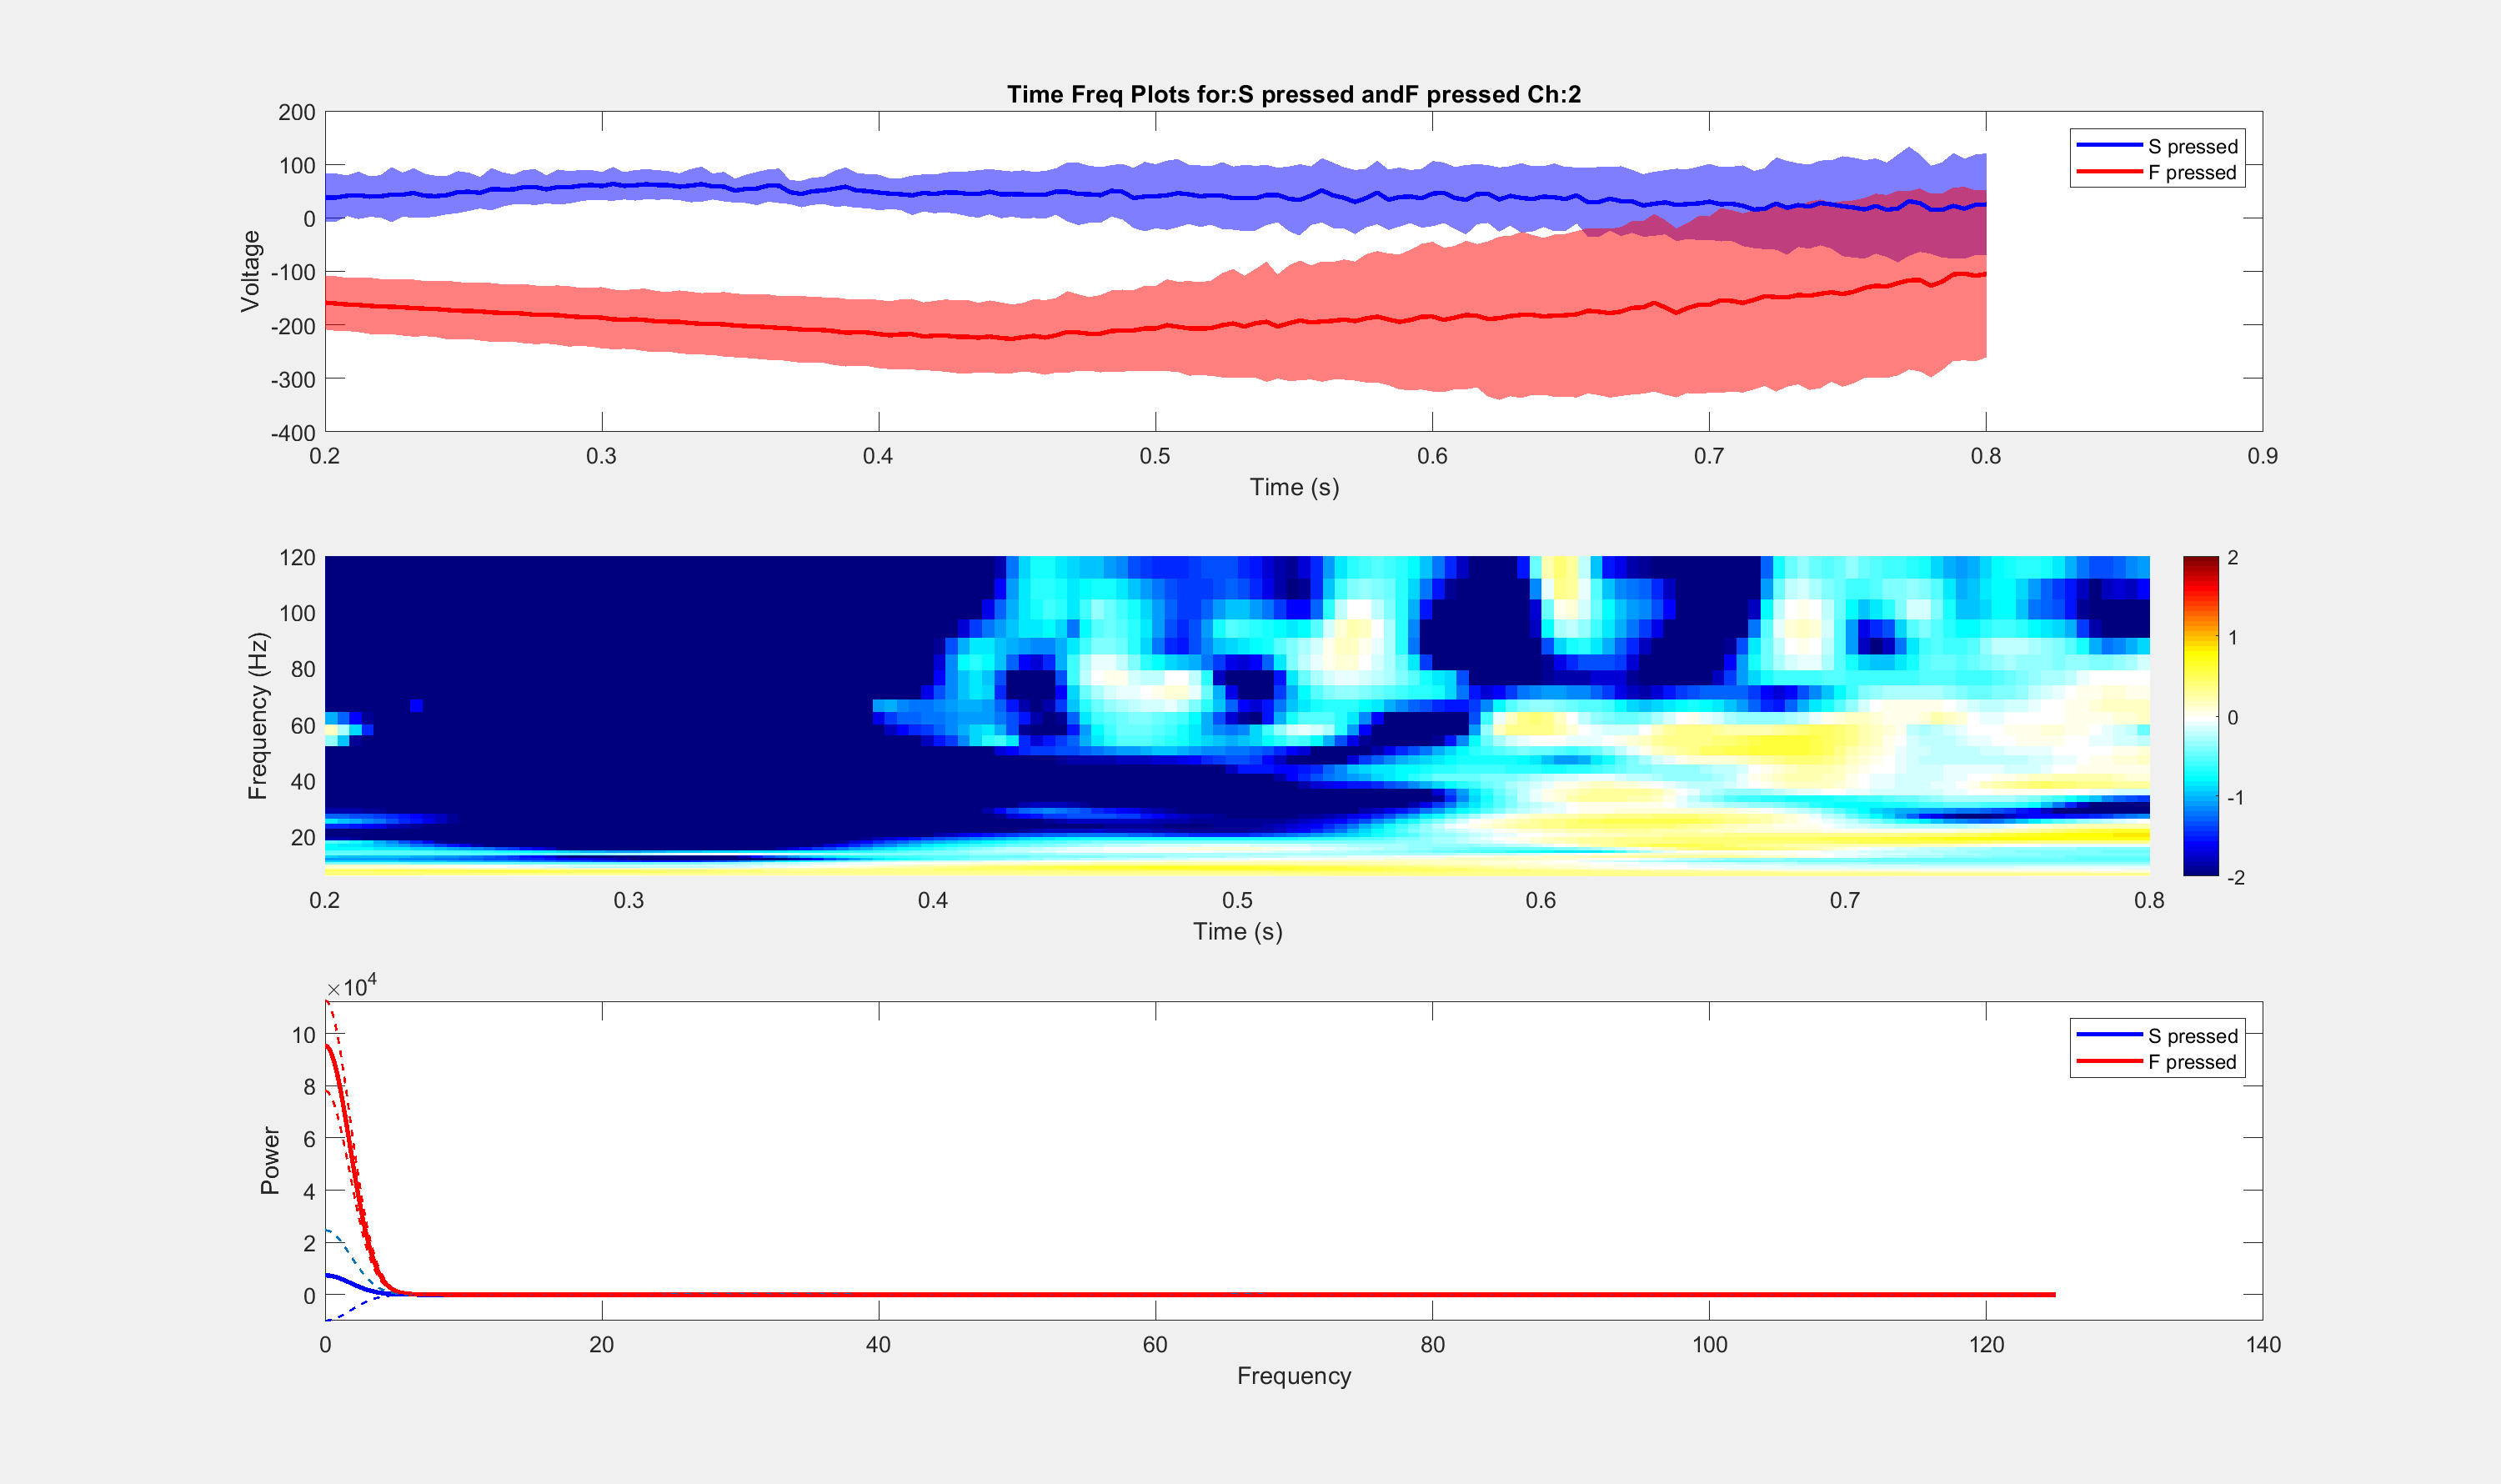

a1 = ((size(condstruc(1).cfs,1)-1) .* (condstruc(2).stdcfs.^2));
a2 = ((size(condstruc(2).cfs,1)-1) .* (condstruc(2).stdcfs.^2));
a3 = (size(condstruc(2).cfs,1)+size(condstruc(2).cfs,1)-2);
pooledstd = sqrt((a1+a2)./a3);
zish = (condstruc(2).meancfs - condstruc(1).meancfs)./(pooledstd);


figure
set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
% Time series
subplot(3,1,1)
plot(EEG.timessec(timewindowepochidx), condstruc(1).meantimecourse,'b','LineWidth',2);
hold on
plot(EEG.timessec(timewindowepochidx), condstruc(2).meantimecourse,'r','LineWidth',2);

ciplotter(condstruc(1).yCI95timecourse(:,1)+condstruc(1).meantimecourse,condstruc(1).yCI95timecourse(:,2)+condstruc(1).meantimecourse,EEG.timessec(timewindowepochidx),'b',.5);
ciplotter(condstruc(2).yCI95timecourse(:,1)+condstruc(2).meantimecourse,condstruc(2).yCI95timecourse(:,2)+condstruc(2).meantimecourse,EEG.timessec(timewindowepochidx),'r',.5);
plot(EEG.timessec(timewindowepochidx), condstruc(1).meantimecourse,'b','LineWidth',2);
plot(EEG.timessec(timewindowepochidx), condstruc(2).meantimecourse,'r','LineWidth',2);
legend(condnames)
ylabel('Voltage'); xlabel('Time (s)');
title(strcat('Time Freq Plots for: ', condnames{1},' and ',condnames{2},' Ch: ', num2str(channel)));
%Continuous wavelet transform (average)
subplot(3,1,2)
%surface(tms,frq,abs(cfs))
%surface(tms,frq,abs(meancfs))
surface(tms,frq,zish); % not sure if this is right log?
colorbar;
colormap(cmapwj);
axis tight
shading flat
xlabel('Time (s)')
ylabel('Frequency (Hz)')
caxis([-2 2])
%set(gca,'yscale','log')

% Plot the mean power 
subplot(3,1,3)

plot(EEG.freqcalcswindow.F, condstruc(1).freqcalcswindow.meanP,'b','LineWidth',2);
hold on
plot(EEG.freqcalcswindow.F, condstruc(2).freqcalcswindow.meanP,'r','LineWidth',2);

plot(EEG.freqcalcswindow.F, condstruc(1).freqcalcswindow.meanP-(2.*condstruc(1).freqcalcswindow.stdP),'b--','LineWidth',1);
plot(EEG.freqcalcswindow.F, condstruc(1).freqcalcswindow.meanP+(2.*condstruc(1).freqcalcswindow.stdP),'--','LineWidth',1);

plot(EEG.freqcalcswindow.F, condstruc(2).freqcalcswindow.meanP-(2.*condstruc(1).freqcalcswindow.stdP),'r--','LineWidth',1);
plot(EEG.freqcalcswindow.F, condstruc(2).freqcalcswindow.meanP+(2.*condstruc(1).freqcalcswindow.stdP),'r--','LineWidth',1);


%ciplotter((condstruc(1).freqcalcswindow.meanP-(2.*condstruc(1).freqcalcswindow.stdP)),condstruc(1).freqcalcswindow.meanP+(2.*condstruc(1).freqcalcswindow.stdP),EEG.freqcalcswindow.F','b',.5);
%ciplotter(condstruc(2).freqcalcswindow.meanP-(2.*condstruc(1).freqcalcswindow.stdP),condstruc(2).freqcalcswindow.meanP+(2.*condstruc(1).freqcalcswindow.stdP),EEG.freqcalcswindow.F','r',.5);
%plot(EEG.freqcalcswindow.F, condstruc(1).freqcalcswindow.meanP,'b','LineWidth',2);
%plot(EEG.freqcalcswindow.F, condstruc(2).freqcalcswindow.meanP,'r','LineWidth',2);
legend(condnames)
ylabel('Power'); xlabel('Frequency');

**This space is to play around with the number of parameters for the cwt**

condnames = {"S pressed","F pressed"};
channel = 1;
clear condstruc idxtrials
for c = 1:length(condnames)
    condname = condnames{c}
    idxtrials = find(EEG.epochlabelscat==condname);

    % Mean of timecourse
    condstruc(c).meantimecourse = mean(squeeze(EEG.data(channel,timewindowepochidx, idxtrials)),2);
    condstruc(c).stdtimecourse = std(squeeze(EEG.data(channel,timewindowepochidx,idxtrials)),0,2);  % Compute 'Standard Error Of The Mean'
    condstruc(c).semtimecourse = condstruc(c).stdtimecourse./sqrt(length(idxtrials)); 
    CI95 = tinv([0.025 0.975], length(idxtrials)-1); % Calculate 95% Probability Intervals Of t-Distribution
    condstruc(c).yCI95timecourse = bsxfun(@times, condstruc(c).semtimecourse, CI95(:)');              % Calculate 95% Confidence Intervals
    
    for i  = 1:length(idxtrials)
        [condstruc(c).cfs(i,:,:),frq] = cwt(double(EEG.data(channel,timewindowepochidx, idxtrials(i))),EEG.srate,...
            'TimeBandwidth',4); %'FrequencyLimits',[2 120],
    end
    tms = EEG.times(timewindowepochidx)./1000; % time axes in seconds% (0:numel(double(EEG.data(channel,timewindowepochidx, idxtrials(1))))-1)/EEG.srate);
    
    condstruc(c).meancfs = squeeze(mean(abs(condstruc(c).cfs),1)); %adding an abs here to get magnitude
    condstruc(c).stdcfs = squeeze(std(abs(condstruc(c).cfs))); % may actually want to do the stdev across all time w/in a freq too
     
end

condname = "S pressed"

condname = "F pressed"

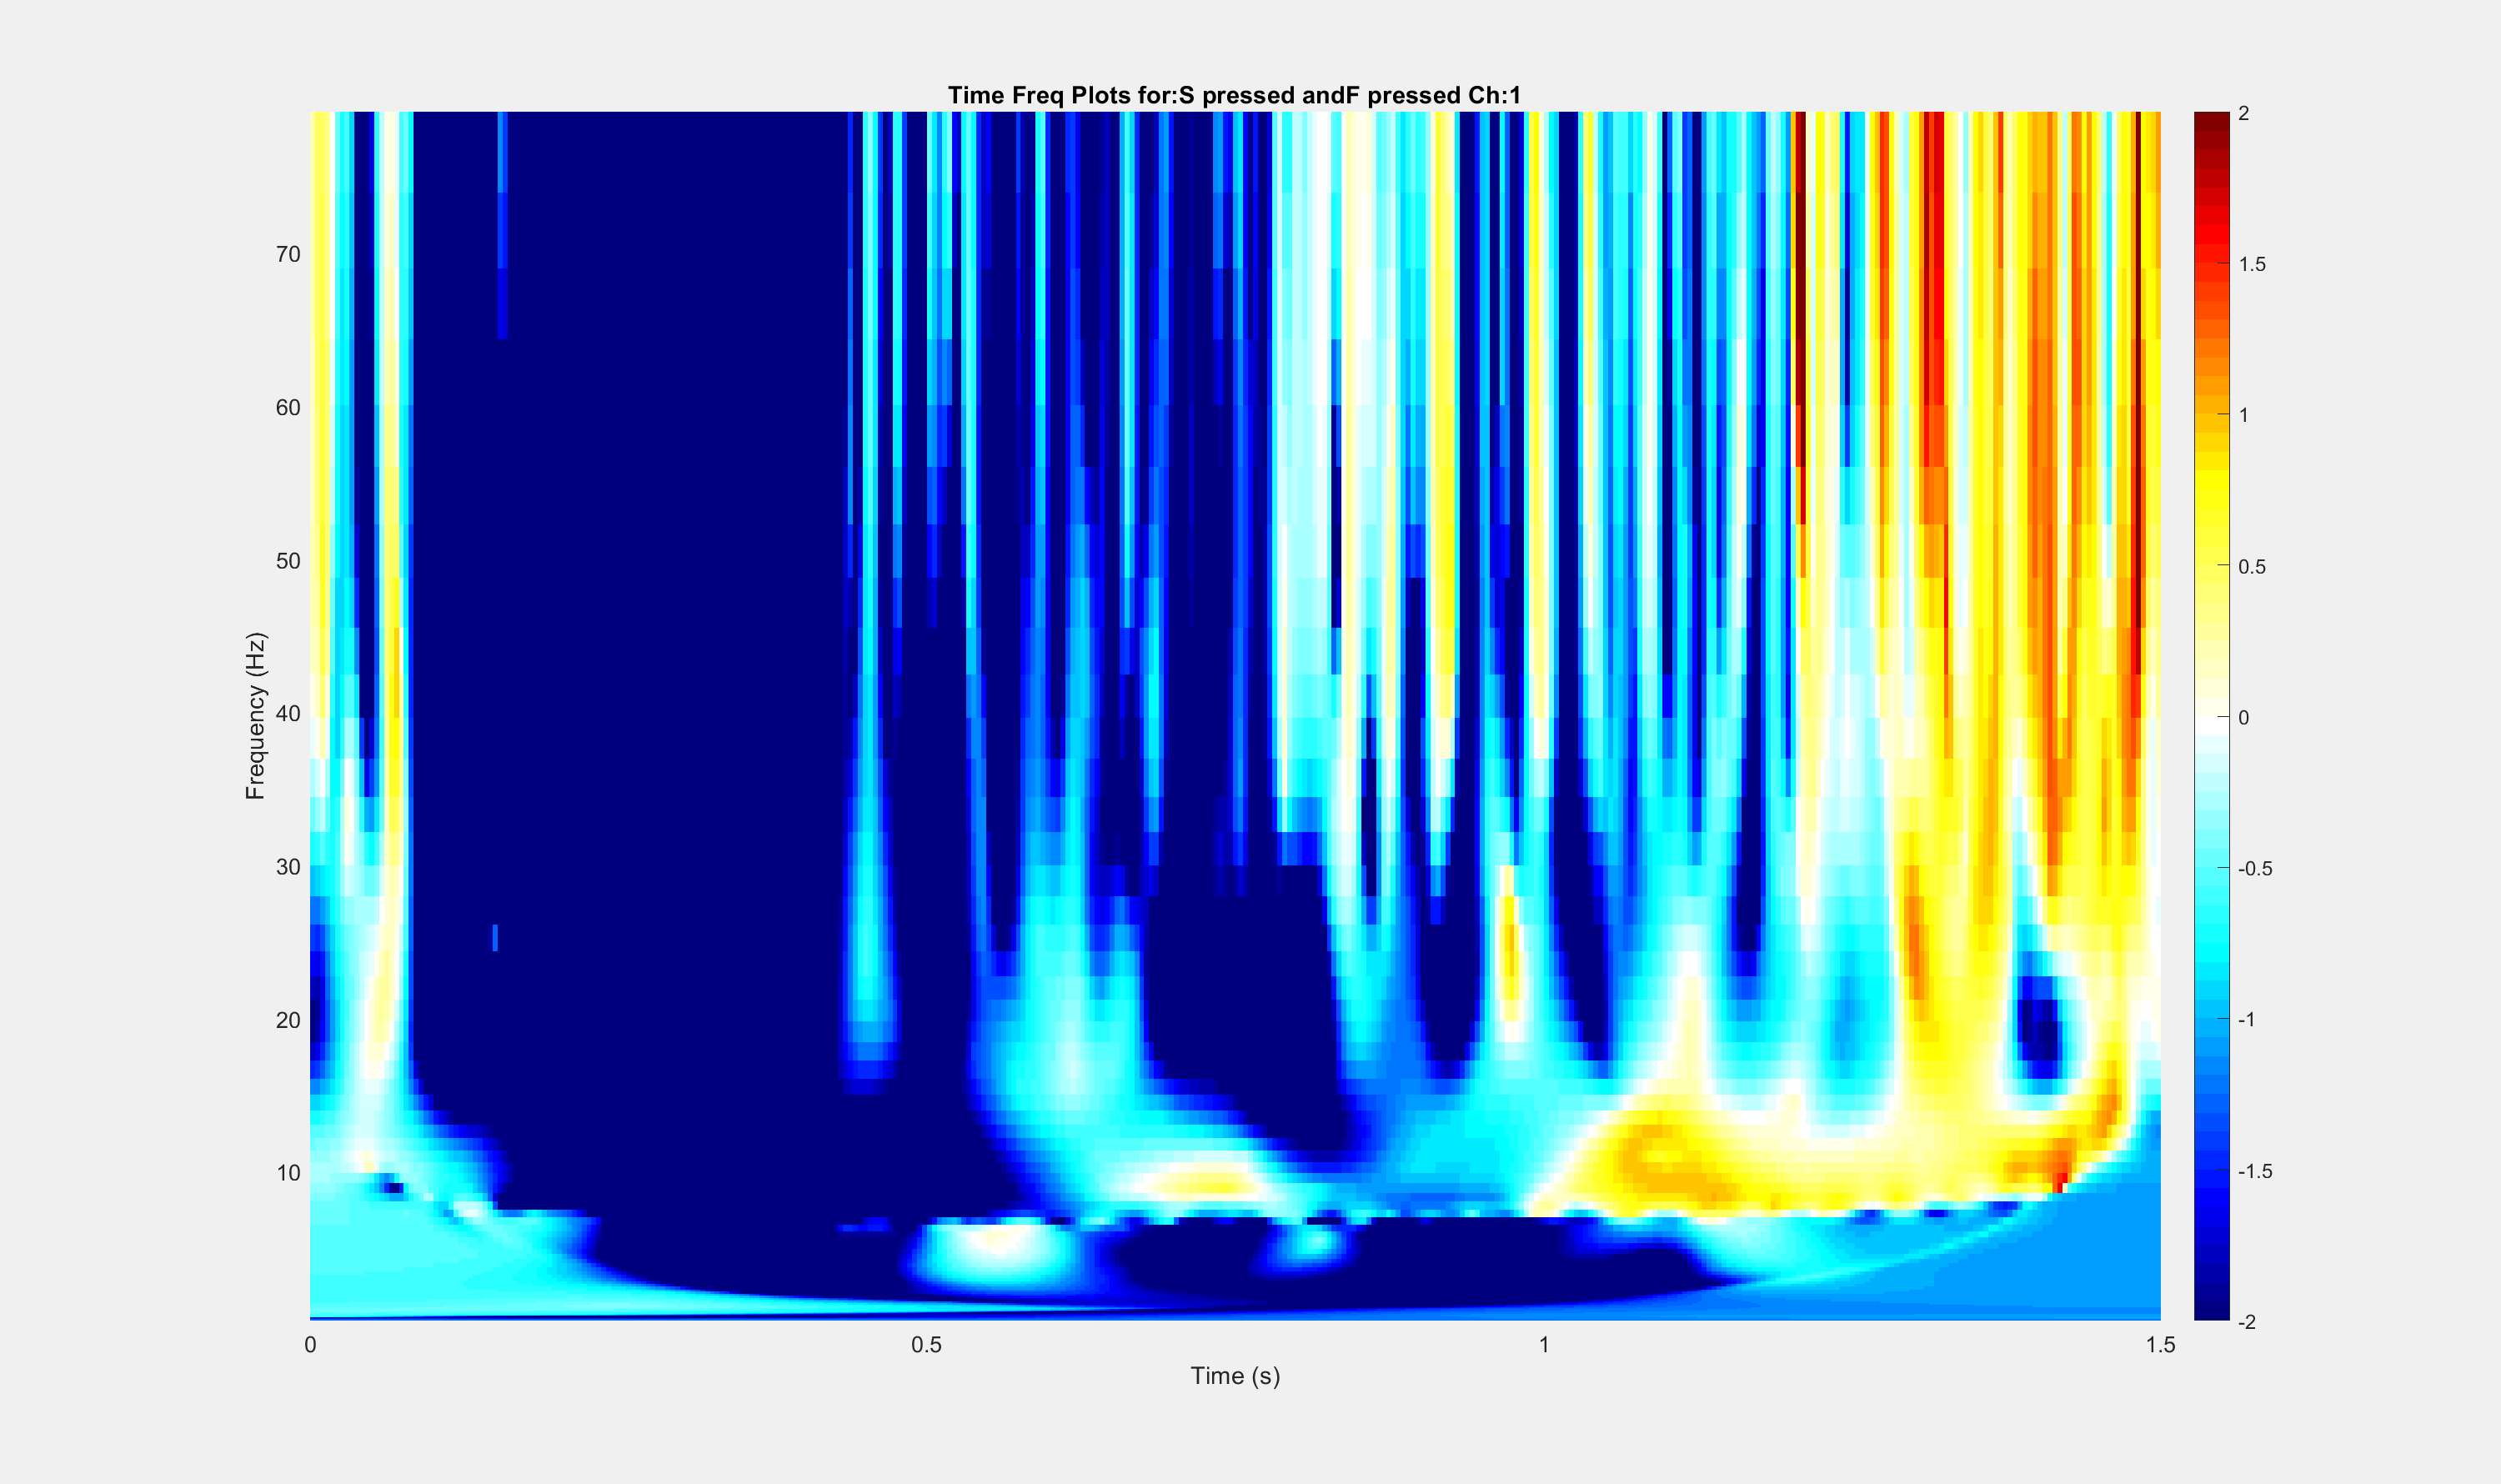


a1 = ((size(condstruc(1).cfs,1)-1) .* (condstruc(2).stdcfs.^2));
a2 = ((size(condstruc(2).cfs,1)-1) .* (condstruc(2).stdcfs.^2));
a3 = (size(condstruc(2).cfs,1)+size(condstruc(2).cfs,1)-2);
pooledstd = sqrt((a1+a2)./a3);
zish = (condstruc(2).meancfs - condstruc(1).meancfs)./(pooledstd);

%Continuous wavelet transform (average)
figure 
set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
surface(tms,frq,zish); % not sure if this is right log?
colorbar;
colormap(cmapwj);
title(strcat('Time Freq Plots for: ', condnames{1},' and ',condnames{2},' Ch: ', num2str(channel)));
axis tight
shading flat
xlabel('Time (s)')
ylabel('Frequency (Hz)')
caxis([-2 2])

### More stuff down here that can be an introduction and some single trials

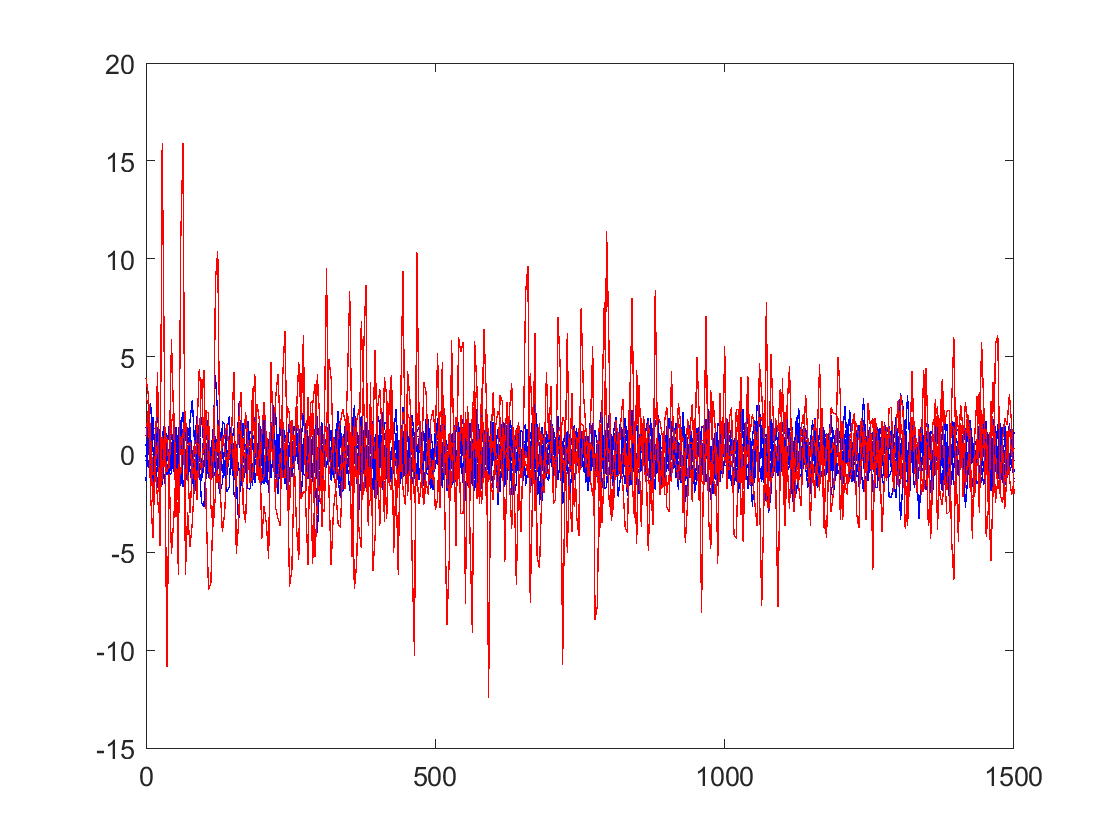

%conditions = ["F pressed","S pressed"];
conditions = ["Completed4","GameOver"];

condcolors = {'b','r'}; %make these blue and red lines, must be at least as long as conditions
channel = 2;

figure
for c = 1:length(conditions)
    idx = find(EEG.epochlabelscat==conditions{c});
    plot(EEG.times(timewindowepochidx), squeeze(EEG.data(channel,timewindowepochidx,idx)),condcolors{c})
    hold on;
%     for ep = idx
%         if length(EEG.epoch(ep).eventlatency) > 2
%             xline(EEG.epoch(ep).eventlatency{3},condcolors{c});
%         end
%     end
end
hold off

Play around with signal processing

% Plot the power vs frequency
%pspectrum(squeeze(EEG.data(channel,timewindowepochidx,5)),EEG.times(timewindowepochidx)./1000) %./1000 to convert to seconds

Make a plot for a single trial

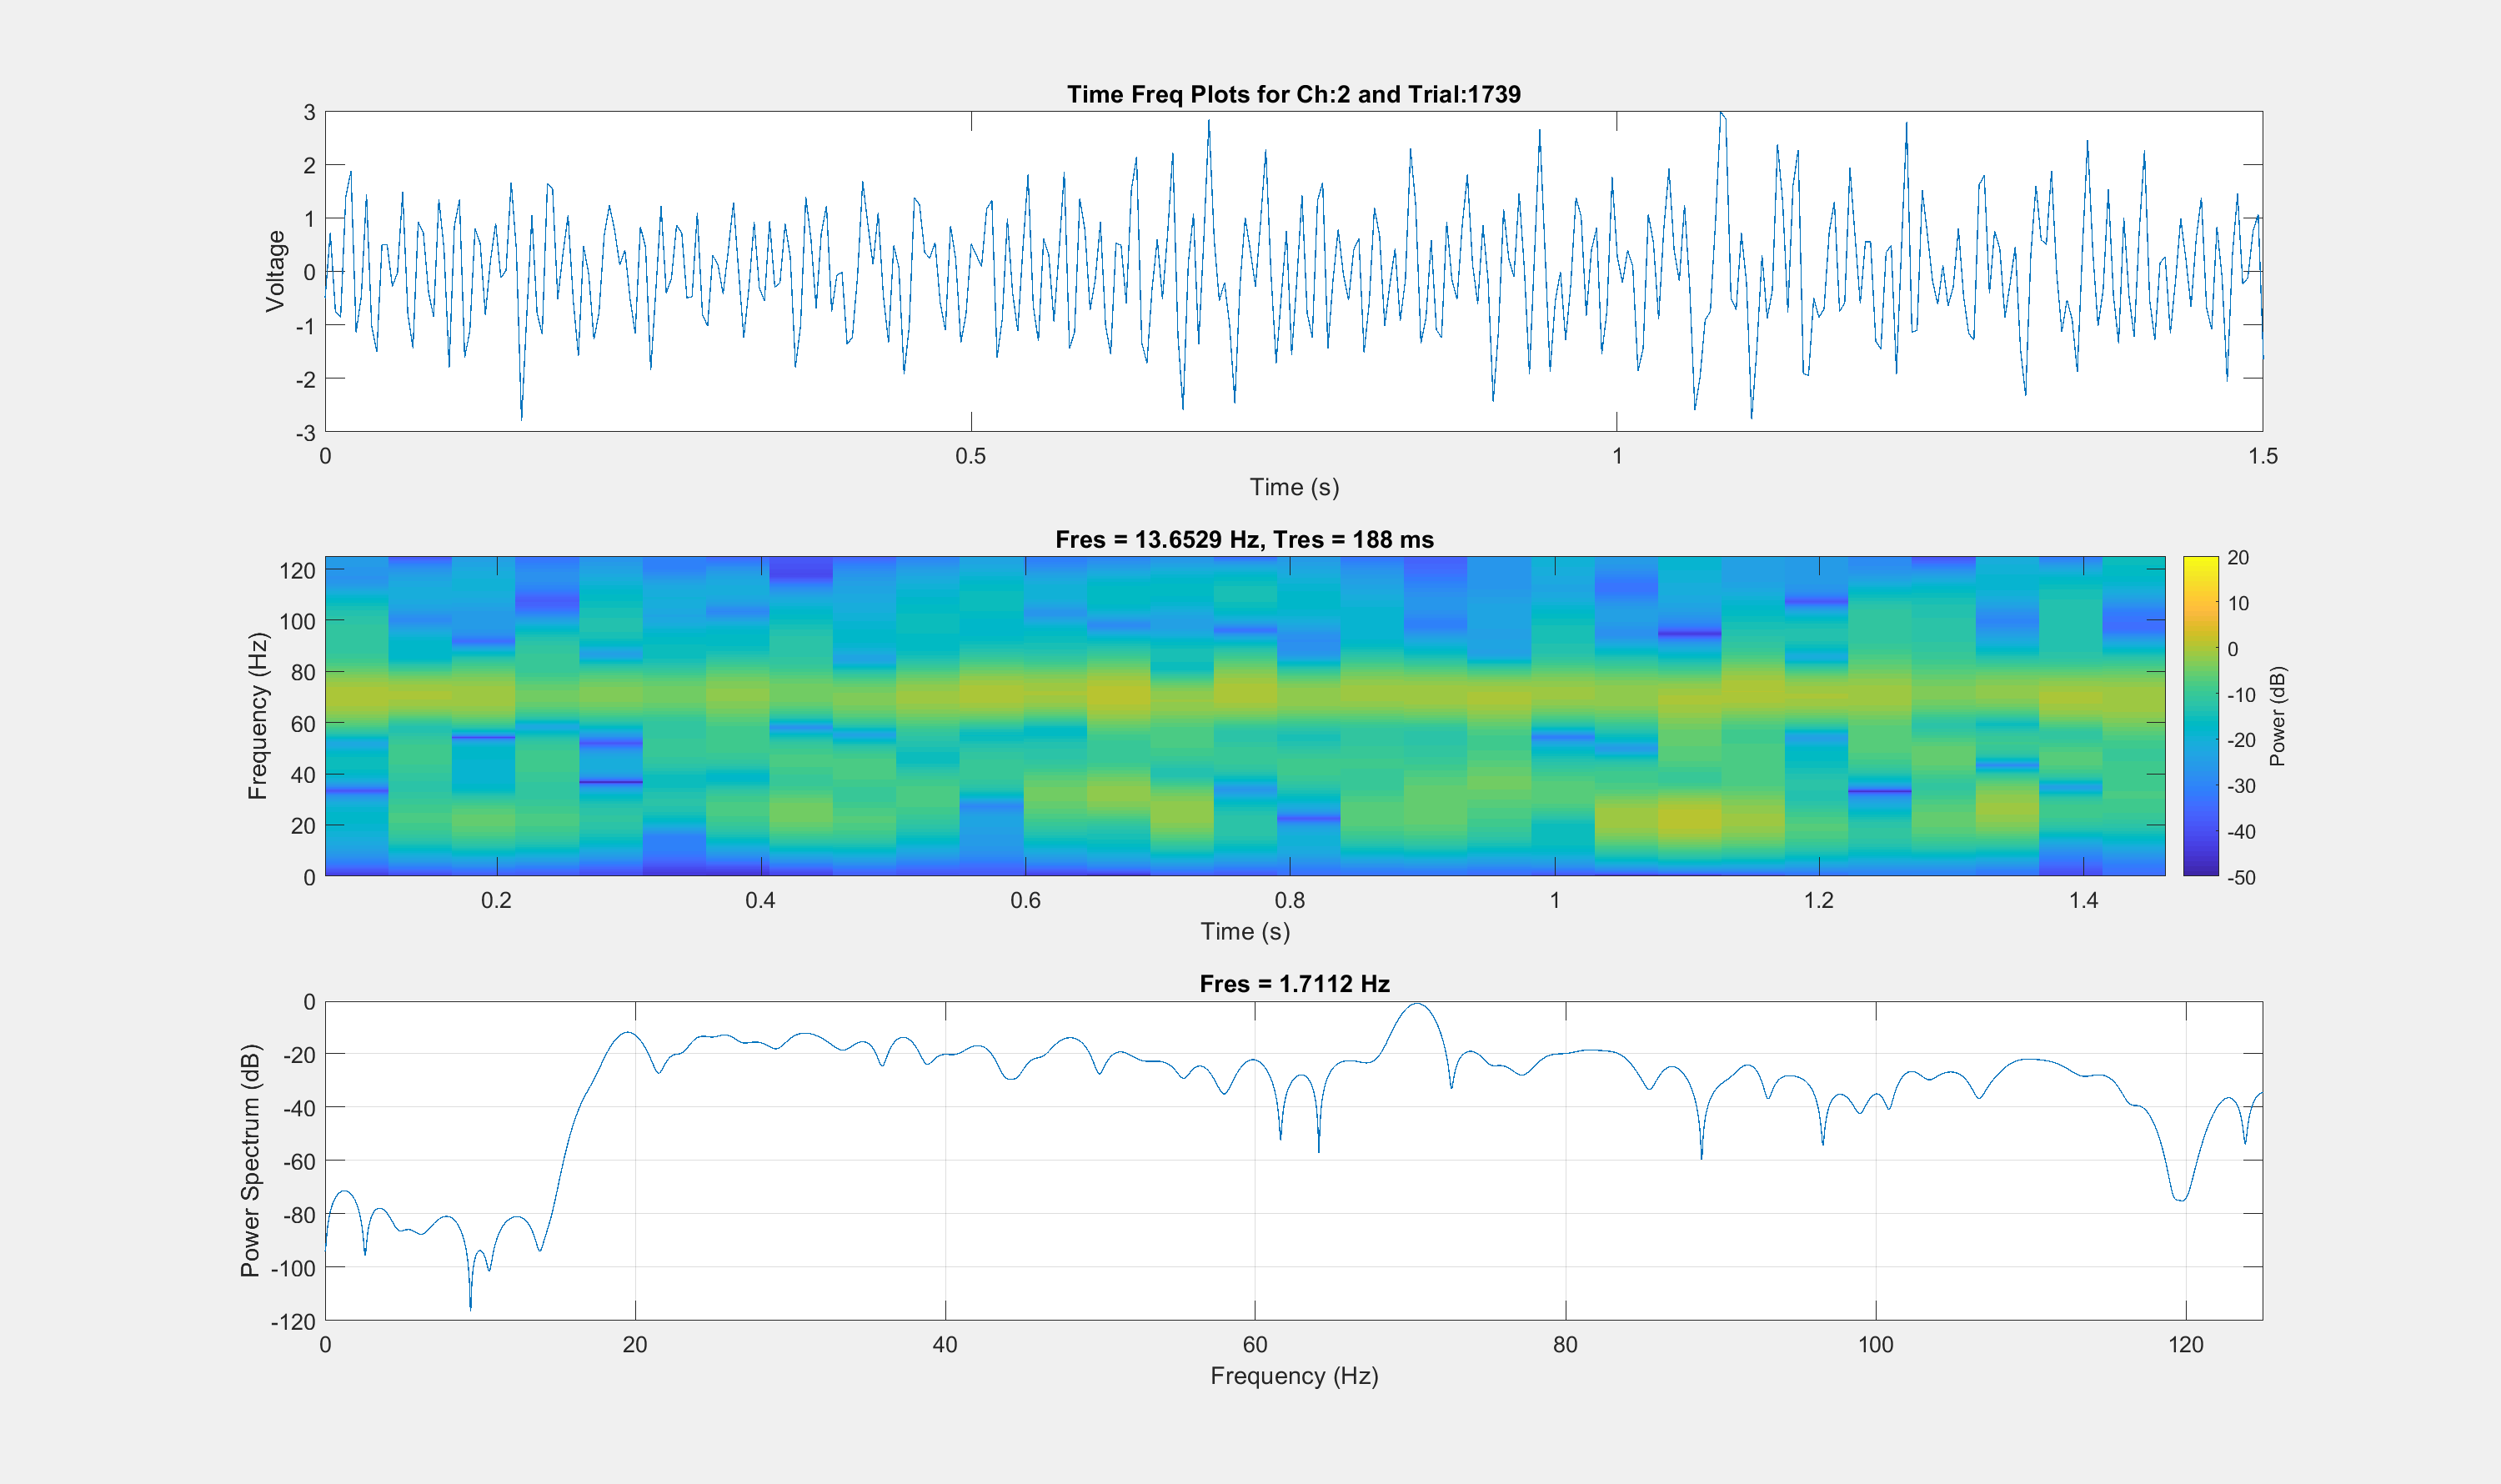

channel = 2;
trial = 1739;%find(EEG.epochlabelscat=="Completed4",1); 
figure
set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
subplot(3,1,1)
plot(EEG.timessec(timewindowepochidx), squeeze(EEG.data(channel,timewindowepochidx,trial))); ylabel('Voltage'); xlabel('Time (s)');
title(strcat('Time Freq Plots for Ch: ', num2str(channel),' and Trial: ', num2str(trial)));
subplot(3,1,2)
pspectrum(squeeze(EEG.data(channel,timewindowepochidx,trial)),EEG.timessec(timewindowepochidx),'spectrogram'); 
caxis([-50 20])
subplot(3,1,3)
pspectrum(squeeze(EEG.data(channel,timewindowepochidx,trial)),EEG.timessec(timewindowepochidx)); 
hold off;

Use a continuous wavelet transform to get a deeper view

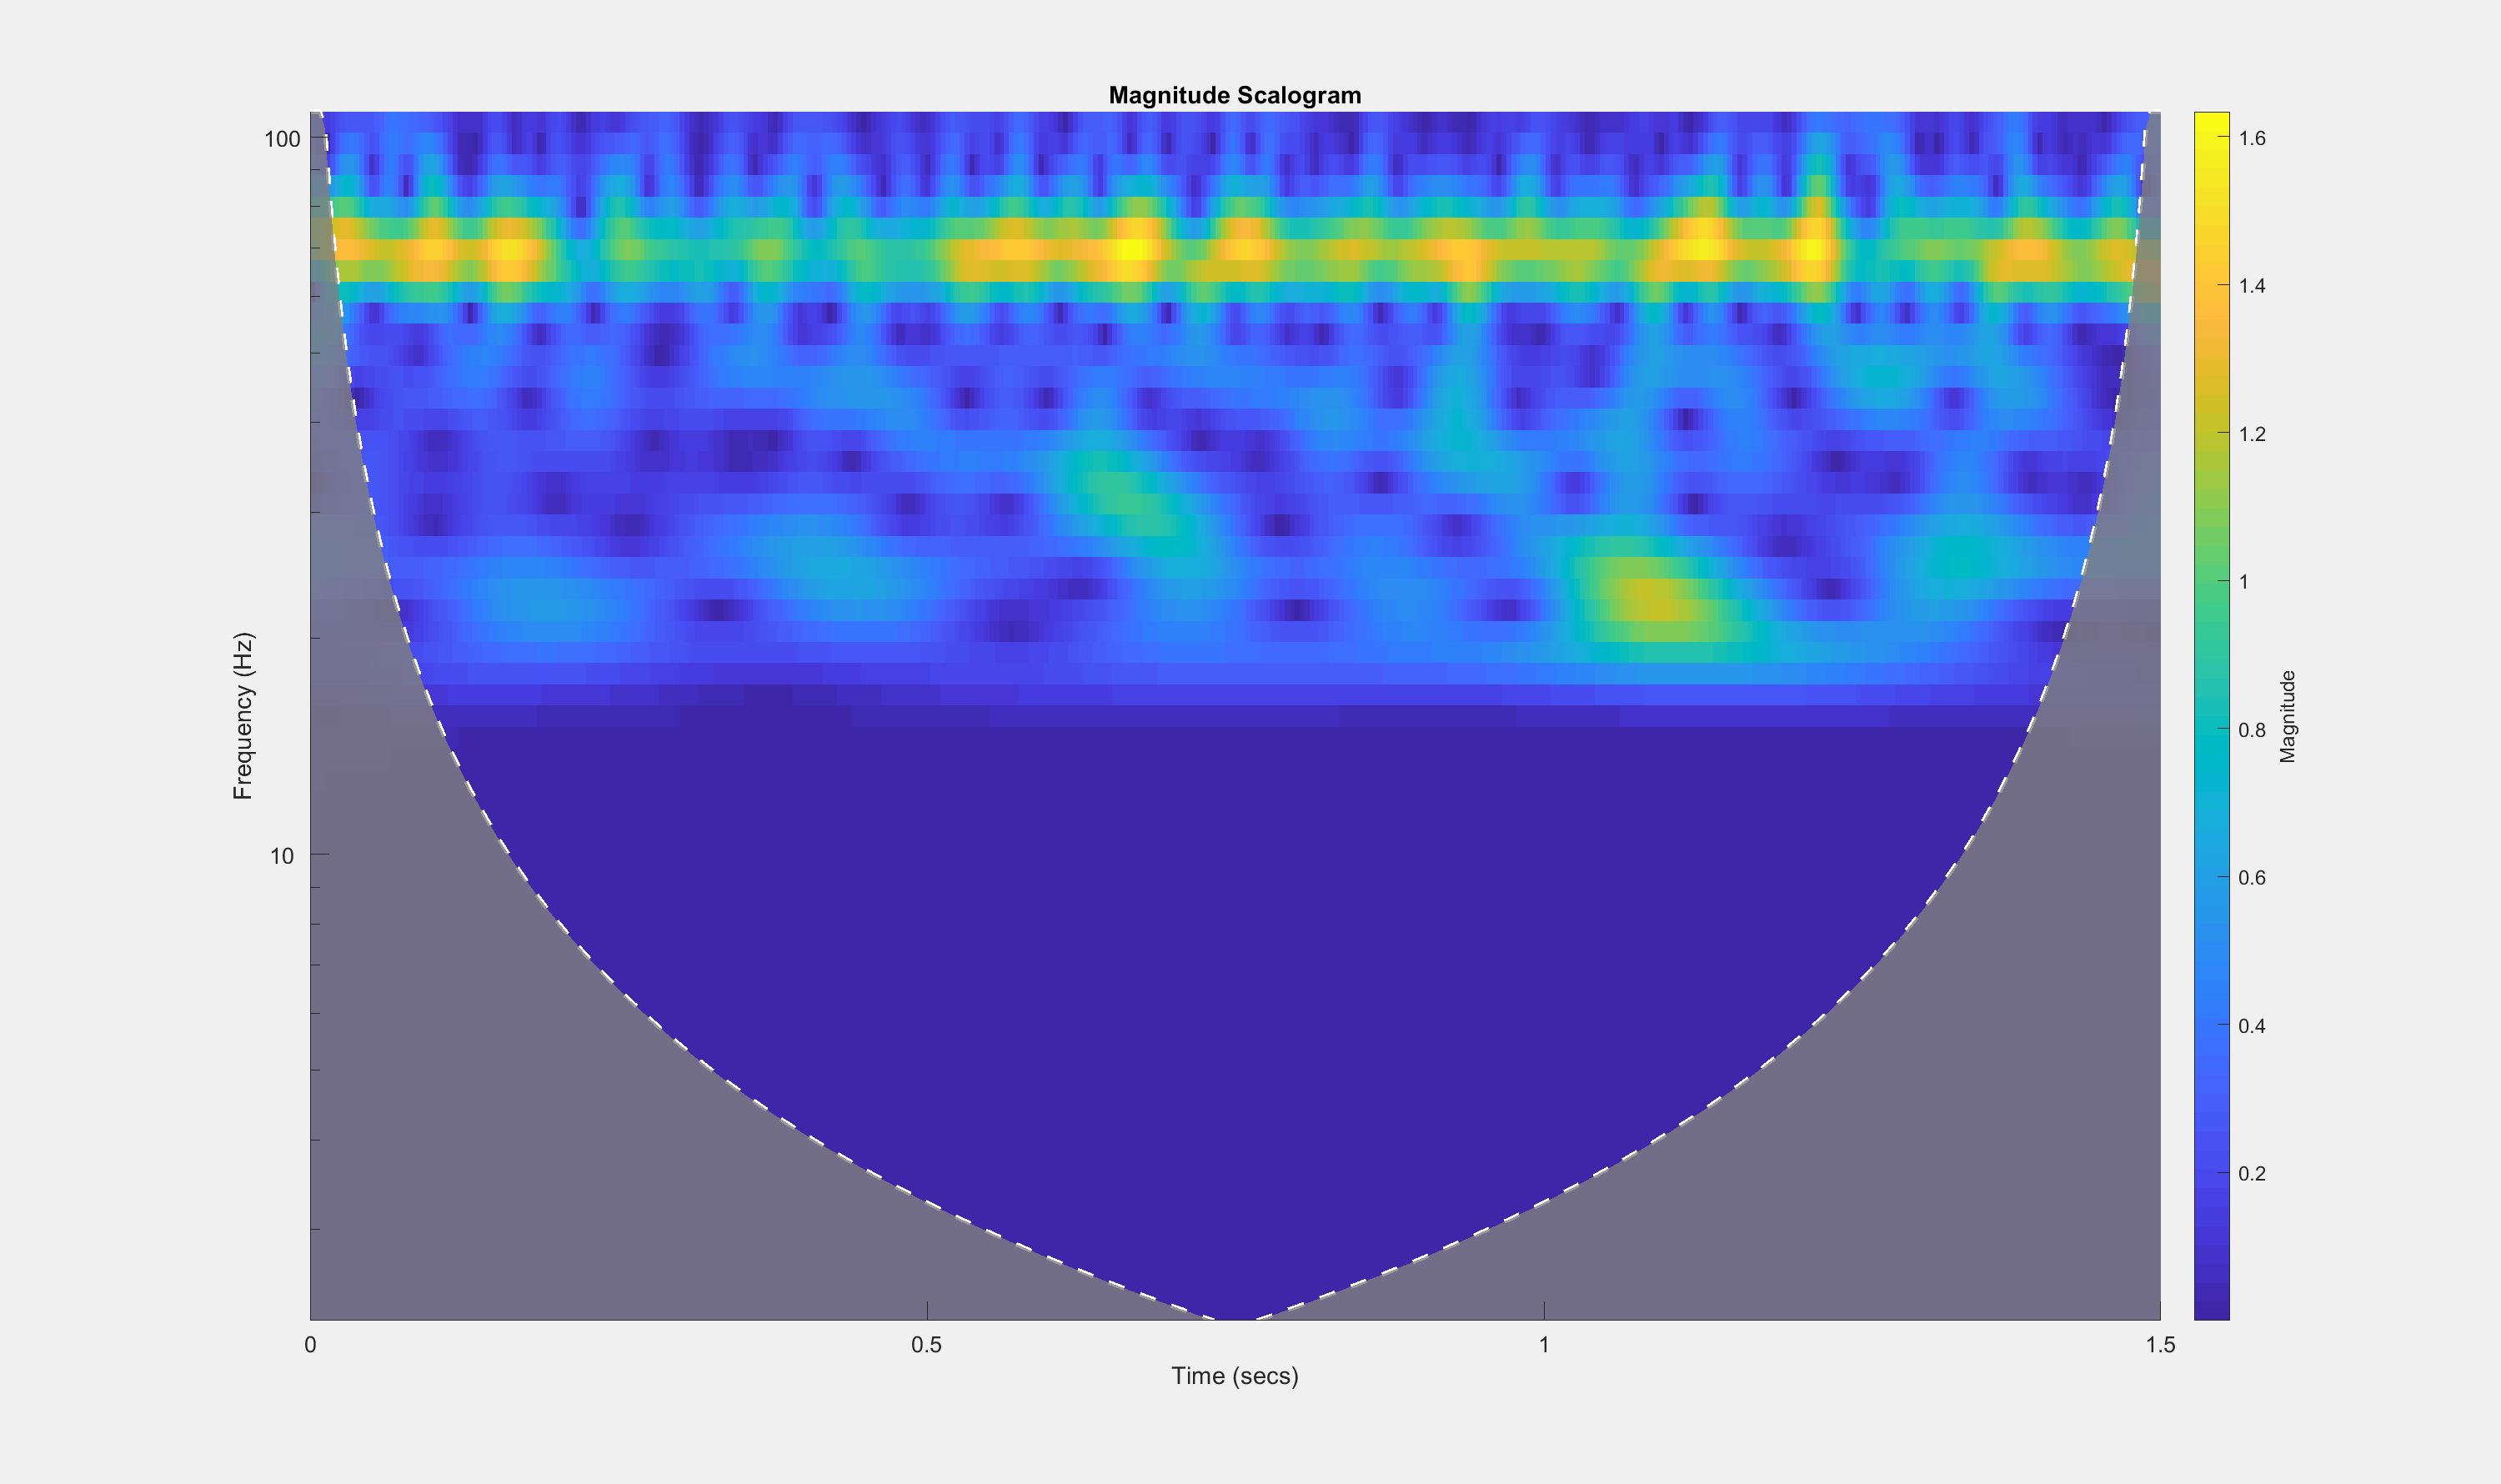

figure;
set(gcf,'Visible','on','WindowState','maximized','Name',strcat('Ch: ', num2str(channel),' and Trial: ', num2str(trial))) % This pops out the figure for easier viewing
cwt(double(squeeze(EEG.data(channel,timewindowepochidx,trial))),EEG.srate);